# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

robotNames = [
    "kinovaGen3";            % 1
    "universalUR3";          % 2
    "universalUR5";          % 3
    "universalUR10";         % 4
    "frankaEmikaPanda";      % 5
    "kukaIiwa7";             % 6
    "rethinkSawyer";         % 7
    "abbIrb120";             % 8
];

endEffectors = [
    "EndEffector_Link";      % 1 kinova
    "tool0";                 % 2 UR3
    "tool0";                 % 3 UR5
    "tool0";                 % 4 UR10
    "panda_hand";            % 5 Franka 
    "iiwa_link_7";           % 6 iiwa7 
    "right_hand";            % 7 sawyer 
    "tool0";                 % 8 abbIrb120
];
%% ✅ 选择机械臂
id =4;  % ← 修改这里来选择机器人 (1=Gen3, 2=UR5, 3=UR10)

robot_name = robotNames(id);
baseEndEffector = endEffectors(id);
robot = loadrobot(robot_name, 'DataFormat','column');

%% 针对不同型号处理末端（仅 Franka 加 TCP 偏移）
endEffector = baseEndEffector;   % 默认：不改末端

% 收集 body 名称（兼容旧版本）
names = strings(length(robot.Bodies),1);
for i = 1:length(robot.Bodies); names(i) = robot.Bodies{i}.Name; end

if robot_name == "frankaEmikaPa"
    % 确保基座末端存在（常见 "panda_hand"；你数组里如果是别名也行）
    if ~any(names == baseEndEffector)
        error('Franka 的末端基座 "%s" 不存在。可用名称：\n%s', ...
            baseEndEffector, strjoin(names, ', '));
    end

    % 如已有 tool，先删避免重复
    if any(names == "tool")
        removeBody(robot,"tool");
    end

    % 根据坐标系定义 TCP 偏移（单位 m）
    % 如果你发现“前方”不是 +Z，可把偏移改为 [0.09 0 0] 或其它方向
    tcpOffset = [0 0 0.1];

    tool = rigidBody("tool");
    jnt  = rigidBodyJoint("toolFix","fixed");
    setFixedTransform(jnt, trvec2tform(tcpOffset));
    tool.Joint = jnt;

    % 把 tool 接到 Franka 的末端基座（如 "panda_hand"）
    addBody(robot, tool, baseEndEffector);

    % 以后统一用 tool 作为末端执行器（指尖 TCP）
    endEffector = "tool";
end

for b = 1:numel(robot.Bodies)
    if ~strcmp(robot.Bodies{b}.Joint.Type,'fixed')
        disp(robot.Bodies{b}.Joint.Name)
    end
end

shoulder_pan_joint
shoulder_lift_joint
elbow_joint
wrist_1_joint
wrist_2_joint
wrist_3_joint




%% 验证
q = homeConfiguration(robot);
T_ee = getTransform(robot, q, endEffector);

fprintf("Selected Robot : %s\n", robot_name);

Selected Robot : universalUR10


%% ✅ 获取关节数量
numJoints = numel(homeConfiguration(robot));

%% ✅ 输出
fprintf("Selected Robot: %s\n", robot_name);

Selected Robot: universalUR10


fprintf("End Effector: %s\n", endEffector);

End Effector: tool0


fprintf("Number of joints: %d\n", numJoints);

Number of joints: 6


Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.2 0.3 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

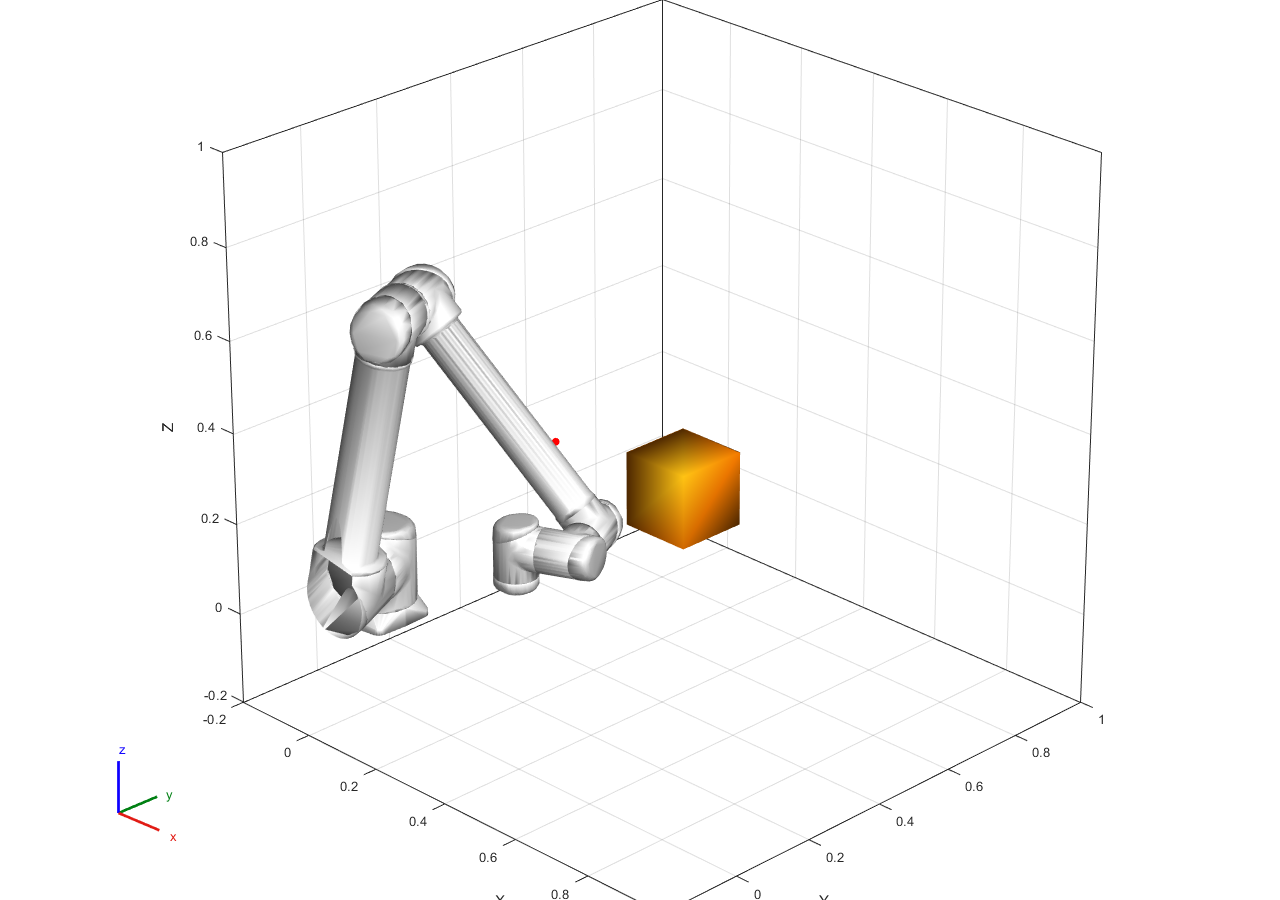

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;
% ==== 放大并规范 3D 视图 ====
fig = gcf; set(fig,'Color','w','Position',[100 100 1280 900]);  % 放大窗口
ax  = gca; view(ax, 45, 25); grid(ax,'on'); box(ax,'on'); hold(ax,'on');
axis(ax,'vis3d'); daspect(ax,[1 1 1]); pbaspect(ax,[1 1 1]);   % 立方比例


xlim(ax,[-0.2, 1]);
ylim(ax,[-0.2, 1]);
zlim(ax,[-0.2, 1]);

camlight(ax,'headlight'); lighting(ax,'gouraud');  % 柔和光照

drawnow;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

    9.6926

   23.7896

     0

    0.2329

    0.5385

    0.5585

     0

    5.6124

    0.5067

    1.3637

    0.0456

    8.6340

  347.1112

    1.7539

    1.3399

   3.2656e+03

    4.2098

    1.6868

    0.5241

   12.5561

  360.2866

    6.4206

历时 0.656282 秒。


Qtheta = 6.4940e+03

RAR = 73.3656

    0.0961

  382.8158

   31.8907

   2.8980e+03

  362.2131

     0

    0.9520

    0.0456

    0.2618

  688.4135

   29.5425

     0

    0.0016

   3.2026e+03

   19.5507

  336.9500

   18.9057

     0

   13.2258

    4.4116

    4.7982

历时 0.654804 秒。


Qtheta = 4.8716e+03

RAR = 73.3660

    2.3701

    0.5373

    0.3166

    0.1326

   13.4633

    0.9086

    0.2834

    2.0940

   15.9112

     0

   3.2351e+03

    2.8151

     0

   18.5628

    0.1765

    0.5343

     0

   23.6639

     0

    0.9034

    3.2551

历时 0.601742 秒。


Qtheta = 3.3284e+03

RAR = 73.3644

   24.7316

     0

    4.6914

    2.2878

     0

    2.2341

     0

   34.8497

     0

    5.1434

    5.1612

    2.8516

     0

    0.2028

    0.7125

    3.6930

     0

    5.5294

    0.0961

   61.9903

    2.1418

历时 0.604260 秒。


Qtheta = 2.2151e+03

RAR = 73.3650

    0.4997

     0

     0

     0

   2.8993e+03

  664.1672

    0.2726

     0

    1.8172

    0.5523

     0

    6.8701

    1.4776

    1.7896

   16.3462

    9.9792

     0

    0.8141

     0

    0.0016

    1.5055

历时 0.592332 秒。


Qtheta = 1.5788e+03

RAR = 73.3638

     0

    1.7092

  349.9489

    1.4736

    0.0456

   31.8812

     0

     0

    1.0198

     0

    4.5914

    1.3434

    0.9860

    7.3550

     0

    5.2246

     0

    8.4650

  353.6526

    0.0283

    0.6066

历时 0.636592 秒。


Qtheta = 679.9145

RAR = 73.3627

  330.5093

   20.6494

   5.4636e+03

   12.4848

   3.2013e+03

  672.9312

     0

     0

     0

     0

    3.8806

     0

     0

    2.8797

    0.0016

    0.0456

    3.6787

     0

     0

     0

    0.4773

历时 0.688439 秒。


Qtheta = 550.6230

RAR = 73.3567

    1.1664

     0

    0.0456

   38.6131

    3.3099

   16.2206

    7.1241

    7.1374

    8.9958

     0

    1.2540

   38.7708

     0

     0

    0.0456

     0

    4.7471

     0

     0

    0.7000

    0.1260

历时 0.601493 秒。


Qtheta = 199.3763

RAR = 73.3528

    0.0456

    0.1417

   25.6895

    4.1152

     0

     0

     0

     0

    0.3038

    0.4127

  664.9061

    0.0456

    0.3182

   10.7190

     0

    1.0334

    2.0561

     0

     0

     0

    0.0978

历时 0.602541 秒。


Qtheta = 171.1038

RAR = 73.3515

    0.1700

    0.1417

   10.0553

     0

     0

    0.1326

    0.6694

    0.7536

     0

   23.3986

    0.0456

     0

     0

     0

    0.9034

     0

     0

    1.4805

    1.0695

     0

    0.0016

历时 0.601214 秒。


Qtheta = 74.9815

RAR = 73.3474

     0

     0

     0

     0

     0

    3.3203

    0.1657

    7.4270

    0.1417

   14.0405

     0

     0

    0.6694

     0

     0

    4.4352

   18.3014

    0.0979

    0.5767

    0.1765

    0.0016

历时 0.603430 秒。


Qtheta = 74.9793

RAR = 73.3452

STOMP Finished.


isTrajectoryInCollision = logical
   0


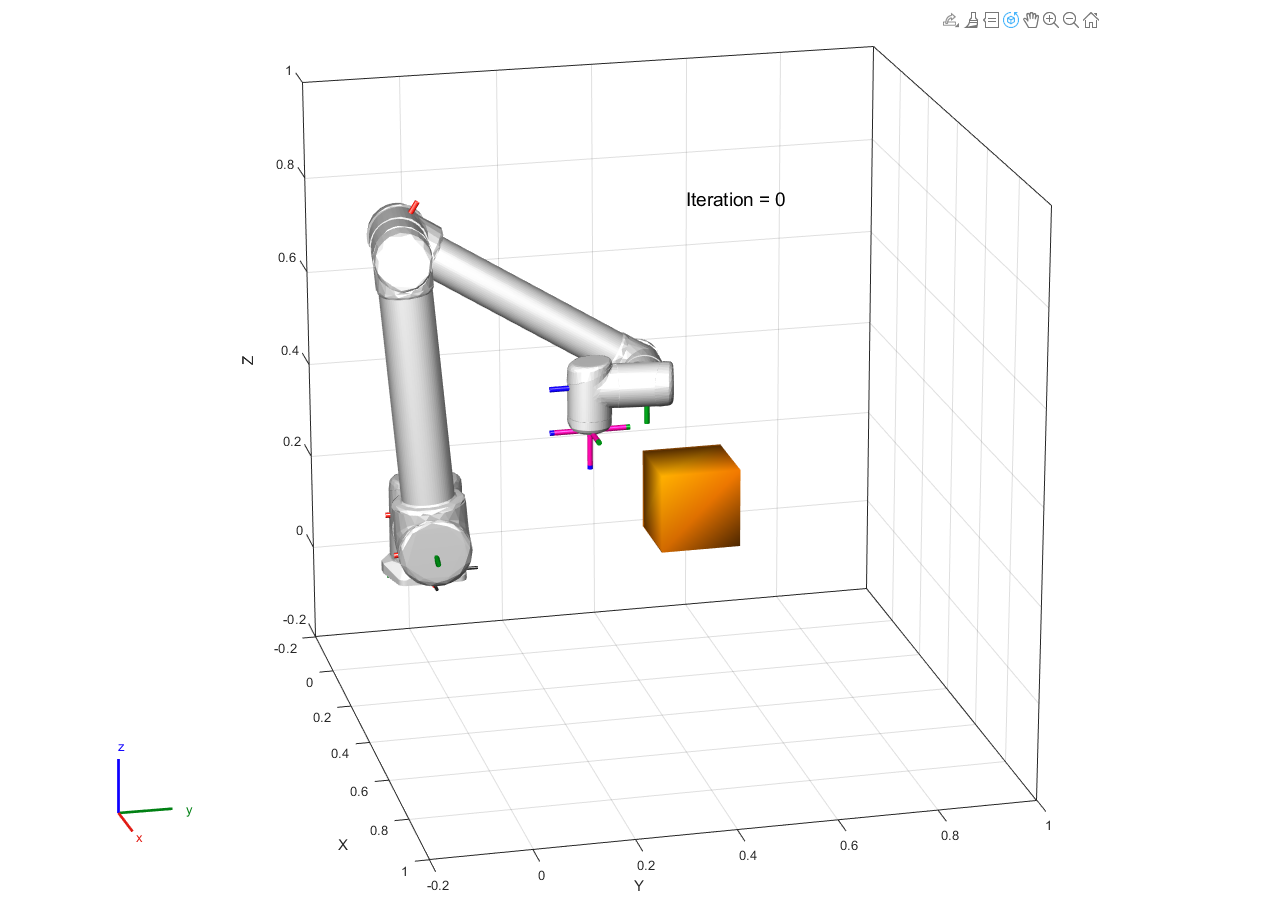

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.